% Filenames
filenames1 = {'02-20-2016_18_19_12'
'02-20-2016_18_18_22'
'02-20-2016_18_17_06'
'02-20-2016_18_16_16'
'02-20-2016_18_15_26'
'02-20-2016_18_14_36'
'02-20-2016_18_13_46'
'02-20-2016_18_12_04'
'02-20-2016_18_11_14'
'02-20-2016_18_10_24'
'02-20-2016_18_09_34'
'02-20-2016_18_08_45'
'02-20-2016_18_07_55'
'02-20-2016_18_07_05'
'02-20-2016_18_06_15'
'02-20-2016_18_05_25'
'02-20-2016_18_04_36'
'02-20-2016_18_03_46'
'02-20-2016_18_02_56'
'02-20-2016_18_02_06'
'02-20-2016_18_01_16'
'02-20-2016_18_00_27'
'02-20-2016_17_59_37'
'02-20-2016_17_58_47'
'02-20-2016_17_57_57'
'02-20-2016_17_57_07'
'02-20-2016_17_56_18'
'02-20-2016_17_55_28'
'02-20-2016_17_54_38'
'02-20-2016_17_53_48'
'02-20-2016_17_52_58'
'02-20-2016_17_52_08'
'02-20-2016_17_48_38'
'02-20-2016_17_44_35'}; % 130,388
filenames2 = {'02-20-2016_21_59_51'
'02-20-2016_21_59_02'
'02-20-2016_21_58_14'
'02-20-2016_21_57_25'
'02-20-2016_21_56_36'
'02-20-2016_21_55_47'
'02-20-2016_21_54_58'
'02-20-2016_21_54_09'
'02-20-2016_21_42_42'
'02-20-2016_21_41_53'
'02-20-2016_21_41_04'
'02-20-2016_21_40_16'
'02-20-2016_21_39_27'
'02-20-2016_22_03_27'
'02-20-2016_22_01_29'
'02-20-2016_22_00_40'
'02-20-2016_22_06_42'
'02-20-2016_22_05_53'
'02-20-2016_22_05_05'
'02-20-2016_22_04_16'}; % 149 404

filenames3={'02-21-2016_ 0_37_08'
'02-21-2016_ 0_36_19'
'02-21-2016_ 0_35_15'
'02-21-2016_ 0_38_48'
'02-21-2016_ 0_37_58'
'02-21-2016_ 0_39_37'
'02-21-2016_ 0_41_55'
'02-21-2016_ 0_42_45'
'02-21-2016_ 0_44_25'
'02-21-2016_ 0_46_04'
'02-21-2016_ 0_47_07'
'02-21-2016_ 0_47_57'
'02-21-2016_ 0_48_47'
'02-21-2016_ 0_49_36'
'02-21-2016_ 0_51_43'
'02-21-2016_ 0_52_33'
'02-21-2016_ 0_53_23'
'02-21-2016_ 0_54_12'
'02-21-2016_ 0_55_02'
'02-21-2016_ 0_55_52'
'02-21-2016_ 0_56_41'
'02-21-2016_ 0_57_31'
'02-21-2016_ 0_58_21'
'02-21-2016_ 0_59_10'
'02-21-2016_ 1_00_00'
'02-21-2016_ 1_00_50'}; % 142 268

filenames = filenames3;


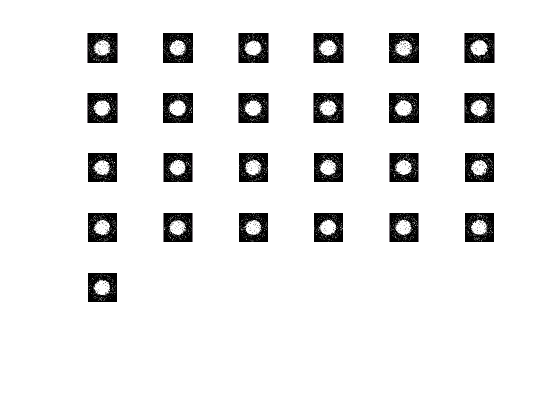

% Load data
data = cell(size(filenames));
atomno = zeros(size(data));
for i = 1:length(data)
    data{i} = imagedata(filenames{i},'crop',{'ellipse',142,268,100,100},'bg',{'avg',10},'plot',{0},'Nsat',3760);
    atomno(i) = sum(sum(getfield(data{i},'od2')));
end

%% Visualize data
figure; subplot(6,6,1);
for i = 1:min(36,length(filenames))
    subplot(6,6,i);
    imshow(getfield(data{i},'od2'),[0 1.5]); set(gca,'YDir','normal');
end


clearvars i ans

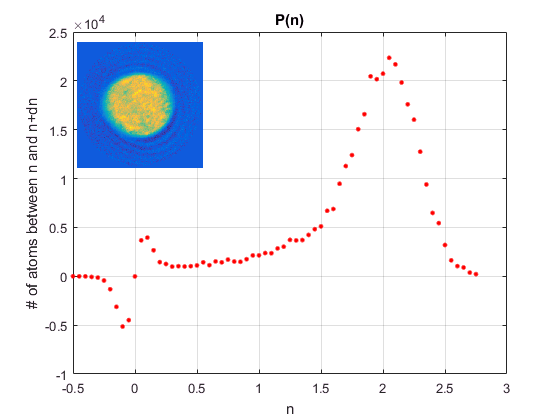

%% P(n) of average
average_od = getfield(data{1},'od2');
for i = 2:length(data), average_od = average_od + getfield(data{i},'od2'); end
average_od = average_od / length(data);
dn_i = 0.05;
n_i_edges = (-0.5:dn_i:2.8)' - dn_i/2;
[n_i,P_n] = extract_Pn(average_od,'plot',1,'plot_nxy_pos',[0.1 0.6 0.3 0.3],'n_i',n_i_edges);

clearvars i dn_i

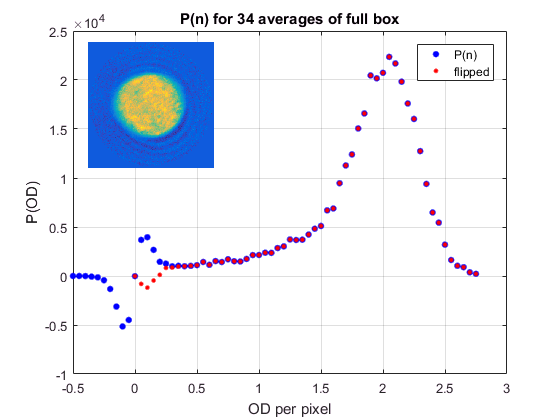

% Folding
ind = find(n_i > -1e-15,1);
P_n_bg = P_n; P_n_bg(ind+1:2*ind-1) = P_n(ind+1:2*ind-1) + flipud(P_n(1:ind-1));
figure;
plot(n_i,P_n,'b.','MarkerSize',15); hold on;
plot(n_i(ind:end),P_n_bg(ind:end),'r.','MarkerSize',10); 
grid on; title('P(n) for 34 averages of full box'); xlabel('OD per pixel'); ylabel('P(OD)');  legend({'P(n)','flipped'}); hold off; 
axes('Position',[0.12 0.6 0.3 0.3]); imagesc(average_od); axis off; axis image;

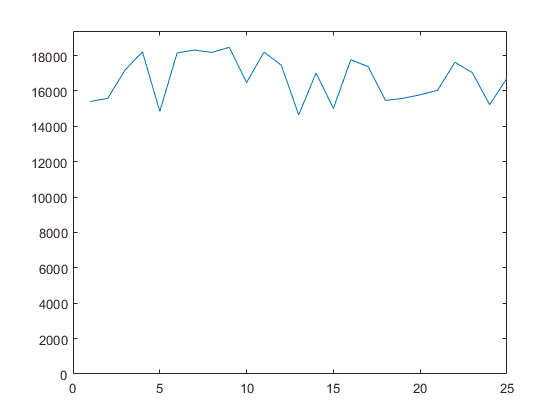

%% Atom number fluctuations
figure; plot(atomno); ylim([0,1.05*max(atomno)]);